% Set training folder path
trainFolder = fullfile(pwd, 'Final Dataset');

% Create datastore from the training folder
imdsFull = imageDatastore(trainFolder, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Split data: 70% training, 15% validation, 15% test
[imdsTrain, imdsRest] = splitEachLabel(imdsFull, 0.7, 'randomized');
[imdsValidation, imdsTest] = splitEachLabel(imdsRest, 0.5, 'randomized');

% Show dataset statistics
fprintf('Train images: %d\n', numel(imdsTrain.Files));

Train images: 9023


fprintf('Validation images: %d\n', numel(imdsValidation.Files));

Validation images: 1934


fprintf('Test images: %d\n', numel(imdsTest.Files));

Test images: 1933


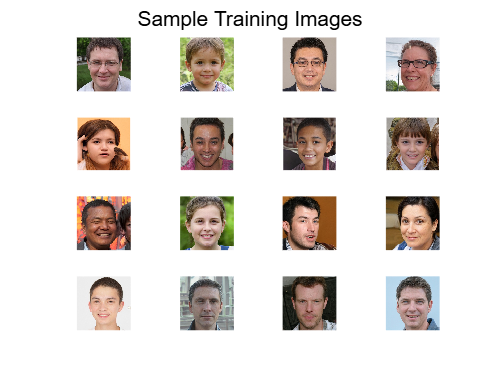


% Visualize training samples
figure;
for i = 1:16
    subplot(4,4,i);
    imshow(readimage(imdsTrain, i));
end
sgtitle('Sample Training Images');


% Load pretrained ResNet-18
net = resnet18;
inputSize = net.Layers(1).InputSize;
numClasses = numel(categories(imdsTrain.Labels));

% Prepare layer graph and modify final layers
lgraph = layerGraph(net);
newFCLayer = fullyConnectedLayer(numClasses, ...
    'Name', 'new_fc', ...
    'WeightLearnRateFactor', 10, ...
    'BiasLearnRateFactor', 10);
newClassLayer = classificationLayer('Name', 'new_class');

% Replace the last layers
lgraph = replaceLayer(lgraph, 'fc1000', newFCLayer);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', newClassLayer);

% Image augmentation
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection', true, ...
    'RandXTranslation', pixelRange, ...
    'RandYTranslation', pixelRange);

% Create augmented datastores
augimdsTrain = augmentedImageDatastore(inputSize(1:2), imdsTrain, 'DataAugmentation', imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2), imdsValidation);
augimdsTest = augmentedImageDatastore(inputSize(1:2), imdsTest);

% Training options
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 32, ...
    'MaxEpochs', 10, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 50, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

% Train the network using ResNet-18
netTransfer = trainNetwork(augimdsTrain, lgraph, options);

% Evaluate on validation data
[YPredVal, ~] = classify(netTransfer, augimdsValidation);
valLabels = imdsValidation.Labels;
valAccuracy = mean(YPredVal == valLabels);
fprintf('Validation Accuracy: %.2f%%\n', valAccuracy * 100);

Validation Accuracy: 92.50%


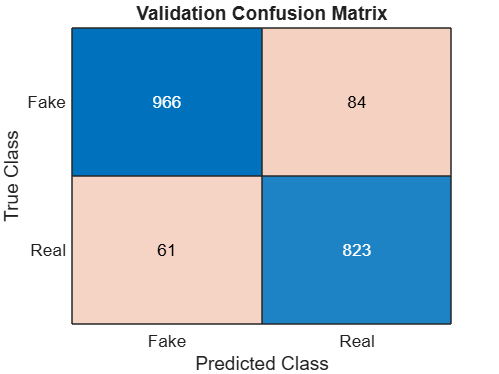

figure; confusionchart(valLabels, YPredVal); title('Validation Confusion Matrix');


% Evaluate on test data
[YPredTest, ~] = classify(netTransfer, augimdsTest);
testLabels = imdsTest.Labels;
testAccuracy = mean(YPredTest == testLabels);
fprintf('Test Accuracy: %.2f%%\n', testAccuracy * 100);

Test Accuracy: 91.93%


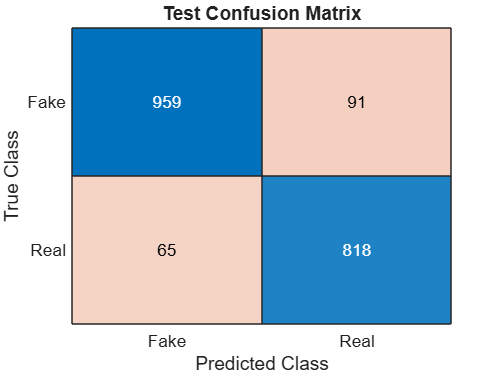

figure; confusionchart(testLabels, YPredTest); title('Test Confusion Matrix');


% Precision, Recall, F1-score
[confMat, order] = confusionmat(testLabels, YPredTest);
TP = confMat(2,2);
TN = confMat(1,1);
FP = confMat(1,2);
FN = confMat(2,1);

precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1 = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 89.99%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 92.64%


fprintf('F1-Score: %.2f%%\n', f1 * 100);

F1-Score: 91.29%


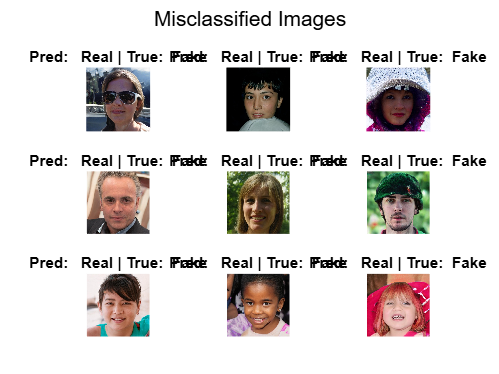


% Visualize misclassified examples
wrongIdx = find(YPredTest ~= testLabels);
figure;
for i = 1:min(9, numel(wrongIdx))
    subplot(3,3,i);
    imshow(readimage(imdsTest, wrongIdx(i)));
    title(['Pred:   ', char(YPredTest(wrongIdx(i))), ' | True:  ', char(testLabels(wrongIdx(i)))]);
end
sgtitle('Misclassified Images');




save('deepfake_model.mat', 'netTransfer'); 
